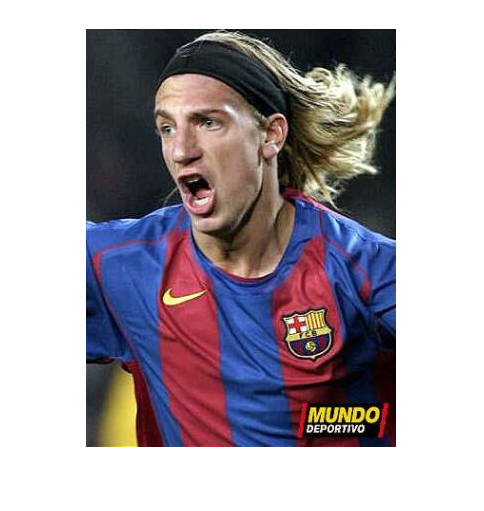

clear all
image=imread('05.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));
row = row/8

row = 52.2500

col = col/8

col = 38.7500


startrow = uint32(row*7)

startrow = uint32
366

startcol = uint32(col*4)

startcol = uint32
155


endrow = uint32(row*8)

endrow = uint32
418

endcol = uint32(col*5)

endcol = uint32
194

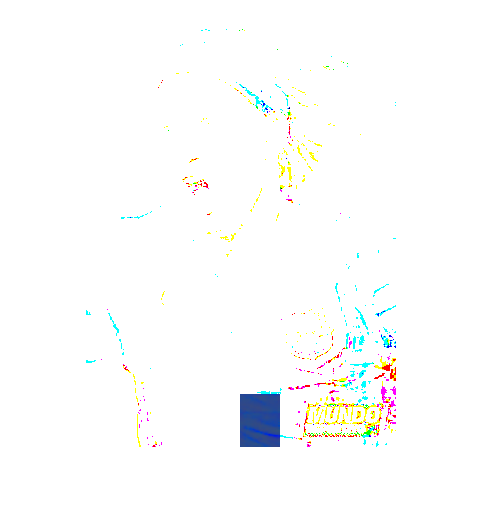


for y = startrow:endrow 
    for x = startcol:endcol 
      Red = Image_red(y,x);
      Green = Image_green(y,x);
      Blue = Image_blue(y,x);
    
      NormalizedRed = Red/(Red + Green + Blue);
      NormalizedGreen = Green/(Red + Green + Blue);
      NormalizedBlue = Blue/(Red + Green + Blue);
    
      Image_red(y,x) = NormalizedRed;
      Image_green(y,x) = NormalizedGreen;
      Image_blue(y,x) = NormalizedBlue;
    end
end
image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

figure; imshow(uint8(255*image));

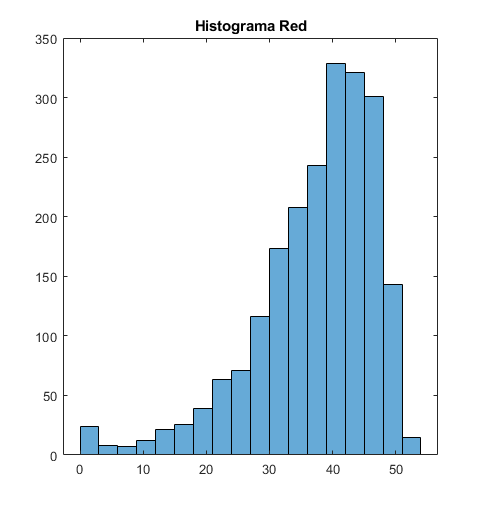


% histogram(image, nBins)
histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')

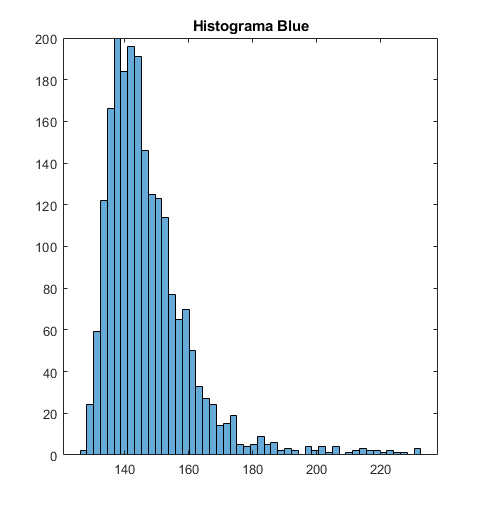

histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')

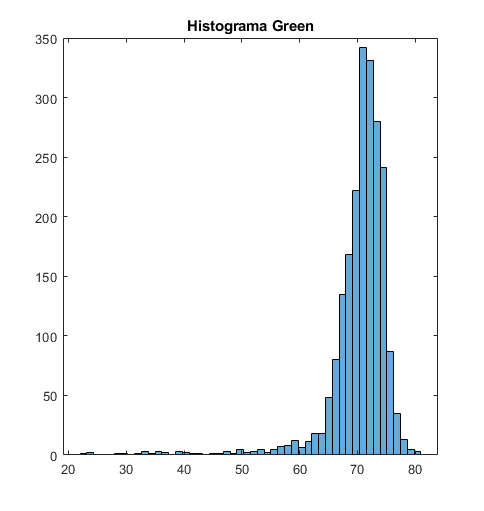

histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')